clc; clear all;

syms lamda

rpm = 2500;

R=0.92/2;
omega = rpm*2*pi/60;
rho = 1.225;
c=0.04;
Nb=2;
sigma = (Nb*c)/(pi*R);
slope = 5.73;
N=10;
r = linspace(0,1,N);
thetaRange = 0:2:11;
theta = thetaRange.*pi/180;
lam=zeros(1,N);
C_T = zeros(1,6);
T = zeros(1,6);

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(1)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt1 = 4.*lam.^2.*r;
C_T(1) = trapz(r,dCt1);
T(1) = C_T(1)*pi*R^4*rho*omega^2;

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(2)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt2 = 4.*lam.^2.*r;
C_T(2) = trapz(r,dCt2);
T(2) = C_T(2)*pi*R^4*rho*omega^2;

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(3)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt3 = 4.*lam.^2.*r;
C_T(3) = trapz(r,dCt3);
T(3) = C_T(3)*pi*R^4*rho*omega^2;

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(4)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt4 = 4.*lam.^2.*r;
C_T(4) = trapz(r,dCt4);
T(4) = C_T(4)*pi*R^4*rho*omega^2;

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(5)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt5 = 4.*lam.^2.*r;
C_T(5) = trapz(r,dCt5);
T(5) = C_T(5)*pi*R^4*rho*omega^2;

for i = 1:N
       
       a = 8*r(i);
       b = sigma*slope*r(i);
       c = sigma*slope*theta(6)*r(i)^2;
       eqn = a*lamda^2 + b*lamda - c == 0;
       soltemp=solve(eqn,lamda);
       soltemp=double(soltemp);
       
       if soltemp == 0
           lam(i) = 0;
       else
           lam(i) = soltemp(2);
       end
   
end

dCt6 = 4.*lam.^2.*r;
C_T(6) = trapz(r,dCt6);
T(6) = C_T(6)*pi*R^4*rho*omega^2;

disp("theta = " + num2str(thetaRange));

theta = 0   2   4   6   8  10


disp("C_T = "+num2str(C_T));

C_T = 0  0.00057127   0.0015711   0.0027358   0.0039958   0.0053199


disp("T = "+num2str(T));

T = 0      6.74677      18.5555      32.3107      47.1908      62.8287


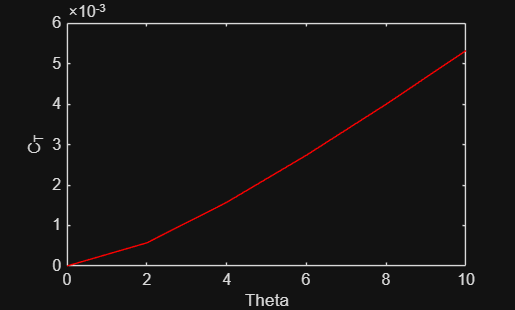

figure
plot(thetaRange,C_T,"Color","r");
xlabel("Theta");
ylabel("C_T");

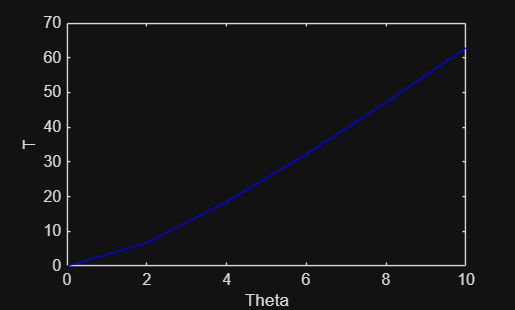

plot(thetaRange,T,"Color","b");
xlabel("Theta");
ylabel("T");